# Simulation of Miips with 2nd order spectral phase

## Set up chirped Gaussian pulse

We set a 5 fs pulse with central wavelength of 800 nm, and a chirp of 100 fs^2.

p = gaussianPulse('f0',300/800, 'fwhm', 5, 'units', 'fs', 'dt', 0.5);

GDD = 100; % fs^2
p.polynomialPhase([GDD 0 0])

## Simulate Miips

The choice of the Miips parameters is crucial for the accuracy of Miips. Specifically one gets more accurate results for low values of 'tau'.

maxGDD = 200; % fs^2
tau = p.calculateShortestDuration();
amp = maxGDD/tau^2;
phasesteps = linspace(-2*pi, 2*pi, 500);

Simulate standard miips

m = IterativeGmiips(p, amp, tau, phasesteps, 'gateWidth', []);

Add a few more iterations each iterations should reduce the error. The property 'retrievedPhase' always stores the cumulative retrieved phase.

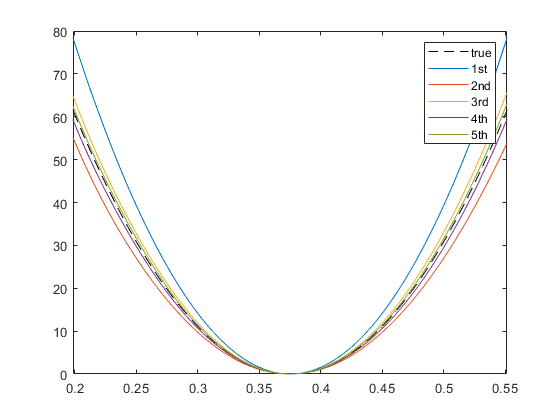

plot(p.frequencyArray, p.spectralPhase, 'k--', m.frequencyArray, m.retrievedPhase);
xlim([-2, 2] * p.bandwidth + p.centralFrequency)
hold on

for i = 1 : 4
    m.newIteration();
    plot(m.frequencyArray, m.retrievedPhase);
end
legend('true', '1st', '2nd', '3rd', '4th', '5th');
hold off

The results of single iterations are available in the 'iterations' property.

If everything goes well, the retrieved phase should decrease at each iteration.

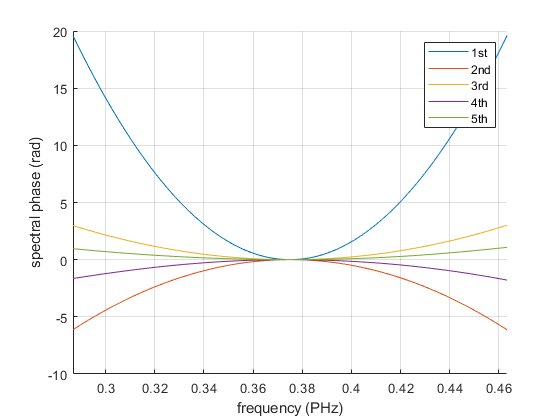

axes(); clf; hold on;  grid on; xlabel('frequency (PHz)'); ylabel('spectral phase (rad)')
for i = 1 : length(m.iterations)
    plot(m.frequencyArray, m.iterations{i}.retrievedPhase);
end
xlim([-1, 1] * p.bandwidth + p.centralFrequency)
legend('1st', '2nd', '3rd', '4th', '5th')